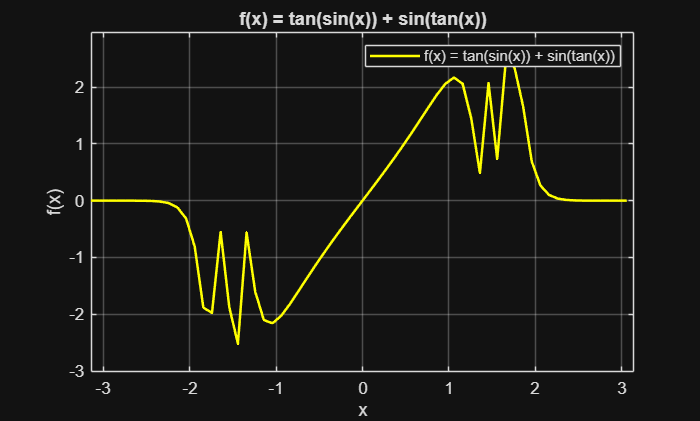

% 2026-09-28
% 3 laboratorinis darbas, privaloma uzduotis
% Jokubas Bridikis

clc; clear; close all;

x = -pi:0.1:pi;
f1 = tan(sin(x)) + sin(tan(x));

figure(1)
plot(x, f1, 'y', 'LineWidth', 1.5)
axis([-pi pi min(f1)-0.5 max(f1)+0.5])
grid on
title('f(x) = tan(sin(x)) + sin(tan(x))')
xlabel('x')
ylabel('f(x)')
legend('f(x) = tan(sin(x)) + sin(tan(x))')

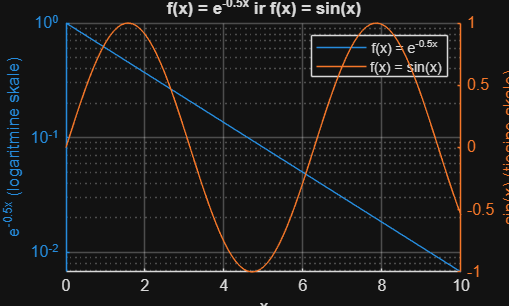


x2 = 0:0.1:10;
f2 = exp(-0.5*x2);
f3 = sin(x2);

figure(2)
[ax, h1, h2] = plotyy(x2, f2, x2, f3, 'semilogy', 'plot');
grid on
title('f(x) = e^{-0.5x} ir f(x) = sin(x)')
xlabel('x')
ylabel(ax(1), 'e^{-0.5x} (logaritmine skale)')
ylabel(ax(2), 'sin(x) (tiesine skale)')
legend([h1 h2], 'f(x) = e^{-0.5x}', 'f(x) = sin(x)')

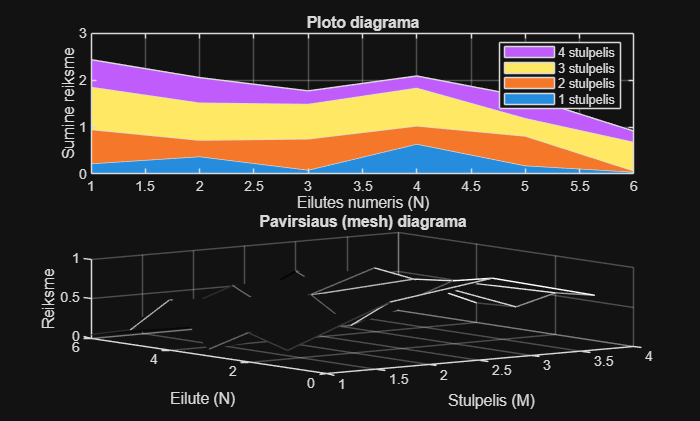


N = 6;
M = 4;
Z = rand(N, M);

figure(3)
subplot(2, 1, 1)
area(Z)
colormap(gray)
grid on
title('Ploto diagrama')
xlabel('Eilutes numeris (N)')
ylabel('Sumine reiksme')
legend('1 stulpelis', '2 stulpelis', '3 stulpelis', '4 stulpelis')

subplot(2, 1, 2)
mesh(Z)
colormap(gray)
title('Pavirsiaus (mesh) diagrama')
xlabel('Stulpelis (M)')
ylabel('Eilute (N)')
zlabel('Reiksme')

## Papildoma uzduotis

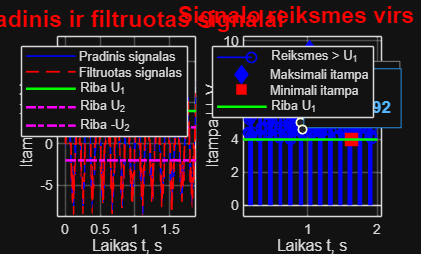

% 2026-09-28
% 3 laboratorinis darbas, papildoma uzduotis
% Jokubas Bridikis

clc; clear; close all;

t = 0:0.002:2;
A = 6;
f = 7;
sigma = 1.2;
U1 = 4;
U2 = 2;

s = A*sin(2*pi*f*t);
n = sigma*randn(size(t));
sn = s + n;

sf = sn;
sf(abs(sf) < U2) = 0;

idx = sn > U1;
ta = t(idx);
sa = sn(idx);

ymax = ceil(max(abs(sn))) + 1;

figure(1)
subplot(1, 2, 1)
plot(t, sn, 'b-', 'LineWidth', 1)
hold on
plot(t, sf, 'r--', 'LineWidth', 1)
plot([t(1) t(end)], [U1 U1], 'g-', 'LineWidth', 1.5)
plot([t(1) t(end)], [U2 U2], 'm-.', 'LineWidth', 1.5)
plot([t(1) t(end)], [-U2 -U2], 'm-.', 'LineWidth', 1.5)
hold off
axis([t(1) t(end) -ymax ymax])
grid on
title('Pradinis ir filtruotas signalai', 'Color', 'r', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('Laikas t, s')
ylabel('Itampa U, V')
legend('Pradinis signalas', 'Filtruotas signalas', 'Riba U_1', 'Riba U_2', 'Riba -U_2')

imax = find(sa == max(sa));
imin = find(sa == min(sa));

subplot(1, 2, 2)
stem(ta, sa, 'b', 'LineWidth', 1)
hold on
plot(ta(imax), sa(imax), 'bd', 'MarkerSize', 10, 'MarkerFaceColor', 'b')
plot(ta(imin), sa(imin), 'rs', 'MarkerSize', 10, 'MarkerFaceColor', 'r')
plot([t(1) t(end)], [U1 U1], 'g-', 'LineWidth', 1.5)
hold off
axis([t(1) t(end) 0 ymax])
grid on
title('Signalo reiksmes virs U_1', 'Color', 'r', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('Laikas t, s')
ylabel('Itampa U, V')
legend('Reiksmes > U_1', 'Maksimali itampa', 'Minimali itampa', 'Riba U_1')